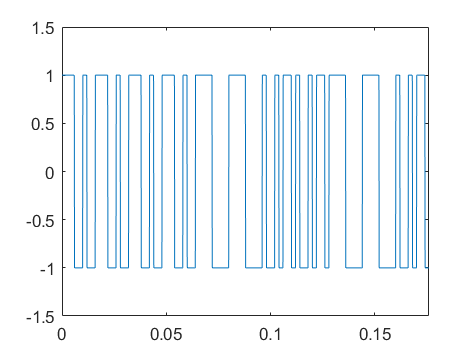

clear all 
close all

% Q9 --------------------------------------------------------
[SeqCDMA1, Fe] = audioread("SeqCDMA1.wav");

Nb_Pts = length(SeqCDMA1);
Te = 1/Fe;
absice = linspace(0, Nb_Pts, Nb_Pts) * Te;

figure(90)
plot(absice, SeqCDMA1)
axis([0 Nb_Pts*Te -1.5 1.5])

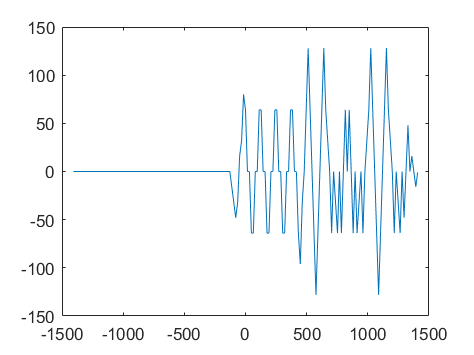


% Variables declaration
ChipTime = 0.002;
Amplitude = 1;

% Definition des codes 
codeWH1 = [ 1  1  1  1  -1 -1 -1 -1 ];
codeWH2 = [ 1 -1 -1  1  -1  1  1 -1 ];
codeWH3 = [ 1 -1  1 -1  -1  1 -1  1 ];
codeWH4 = [ 1  1 -1 -1  -1 -1  1  1 ];
codeBK  = [ 1  1  1 -1  -1  1 -1  0 ];

% Création des symboles
[Symbol_WH1, NbPt_Symbol_WH1 , ~] = FCT_CODE_WH(codeWH1,ChipTime,Fe,Amplitude);
[Symbol_WH2, NbPt_Symbol_WH2 , ~] = FCT_CODE_WH(codeWH2,ChipTime,Fe,Amplitude);
[Symbol_WH3, NbPt_Symbol_WH3 , ~] = FCT_CODE_WH(codeWH3,ChipTime,Fe,Amplitude);
[Symbol_WH4, NbPt_Symbol_WH4 , ~] = FCT_CODE_WH(codeWH4,ChipTime,Fe,Amplitude);
[Symbol_BK,  NbPt_Symbol_BK  , ~] = FCT_CODE_WH(codeBK,ChipTime,Fe,Amplitude);

% Intercorr
[IntercorrCDMA_codeWH1, ~] = xcorr(SeqCDMA1,Symbol_WH1);
[IntercorrCDMA_codeWH2, ~] = xcorr(SeqCDMA1,Symbol_WH2);
[IntercorrCDMA_BK,      ~] = xcorr(SeqCDMA1,Symbol_BK);

NbPt_InterCorr = length(IntercorrCDMA_codeWH1);
absice_InterCorr   = [-(NbPt_InterCorr - 1) / 2 : (NbPt_InterCorr - 1)/2];

% AFFICHAGE INTERCORR
figure(91)
plot(absice_InterCorr, IntercorrCDMA_codeWH1)

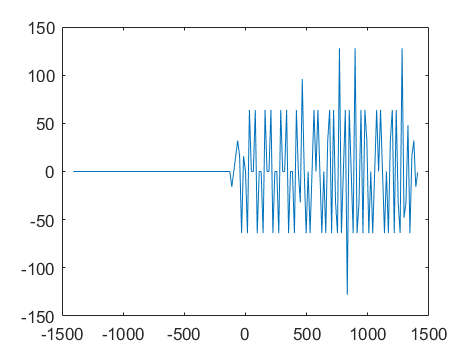

figure(92)
plot(absice_InterCorr, IntercorrCDMA_codeWH2)

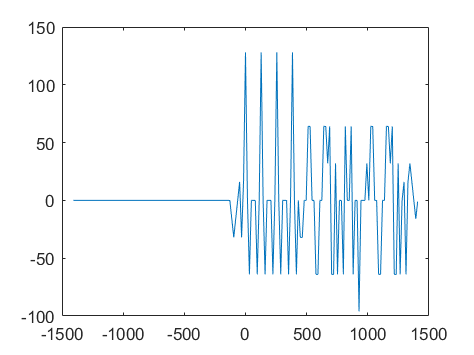

figure(93)
plot(absice_InterCorr, IntercorrCDMA_BK)

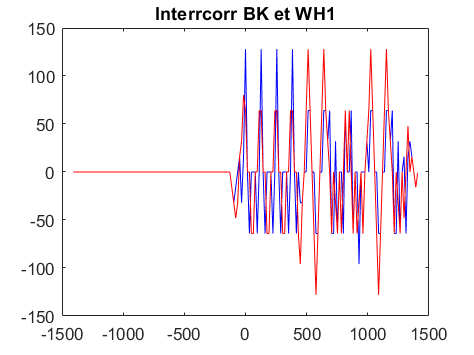


% AFFICHAGE AUTOCORR
figure(111)
plot(absice_InterCorr, IntercorrCDMA_BK, 'b', ...
     absice_InterCorr, IntercorrCDMA_codeWH1, 'r')
title("Interrcorr BK et WH1")

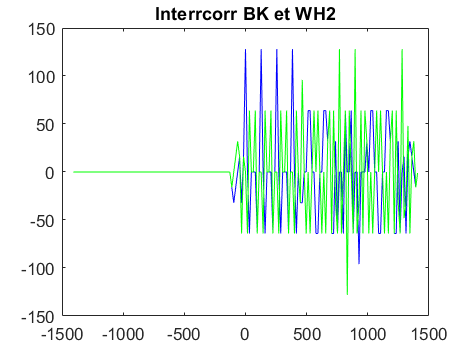


figure(112)
plot(absice_InterCorr, IntercorrCDMA_BK, 'b', ...
     absice_InterCorr, IntercorrCDMA_codeWH2, 'g')
title("Interrcorr BK et WH2")

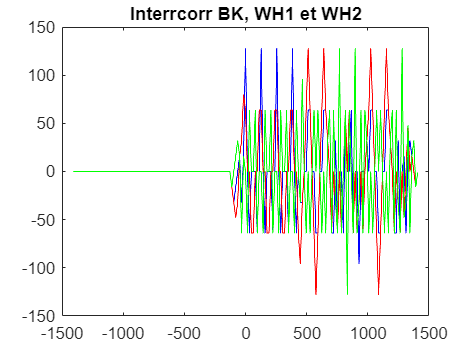


figure(113)
plot(absice_InterCorr, IntercorrCDMA_BK, 'b', ...
     absice_InterCorr, IntercorrCDMA_codeWH1, 'r', ...
     absice_InterCorr, IntercorrCDMA_codeWH2, 'g')
title("Interrcorr BK, WH1 et WH2")


% Declartion du mot
mot = zeros(0, 8);
j = 1;

% Recup le debut de la trame
[ ~, Start_Index] = max(IntercorrCDMA_BK);
%Start_Index = Start_Index + 128*3;

% décode la trame
for i = Start_Index:128:NbPt_InterCorr
    if IntercorrCDMA_codeWH1(i) > IntercorrCDMA_codeWH2(i)
        mot(j) = 1;
    else 
        mot(j) = 0;
    end
    j = j + 1;
end 

mot

mot =      1     1     1     1     0     0     1     1     0
